clear all;
clc;

## `Auto Encoder Modelling:`

### Create a dataset of random binary data sequences for training and testing. 

% Generate random binary data
num_samples = 100000;
sequence_length = 150;

dataset = cell(1, num_samples);

for i = 1:num_samples
    dataset{i} = randi([0, 1], 1, sequence_length);   
end
% Example: Accessing a specific sequence
sample_index = 18;
data_sequence = dataset{sample_index};
% Convert cell arrays to matrices
datasetMatrix = cell2mat(dataset');

#### Spliting train and test data:

% Specify the percentage of data for training
trainPercentage = 90; % Adjust as needed

% Create a random partition for training and testing
cv = cvpartition(size(datasetMatrix, 1), 'HoldOut', 1 - trainPercentage/100);

% Split the data into training and test sets
trainData = datasetMatrix(training(cv), :);
testData = datasetMatrix(test(cv), :);


### Define an autoencoder architecture:

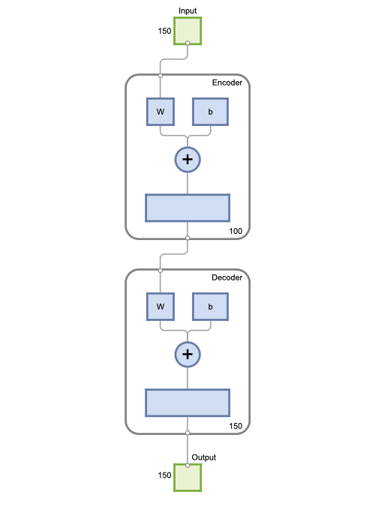

input_size = sequence_length;
hidden_size = 100; % Adjust the number of hidden units as needed

autoencoder = trainAutoencoder(trainData', hidden_size, 'MaxEpochs', 100, 'EncoderTransferFunction', 'logsig', 'DecoderTransferFunction', 'logsig');
view(autoencoder)

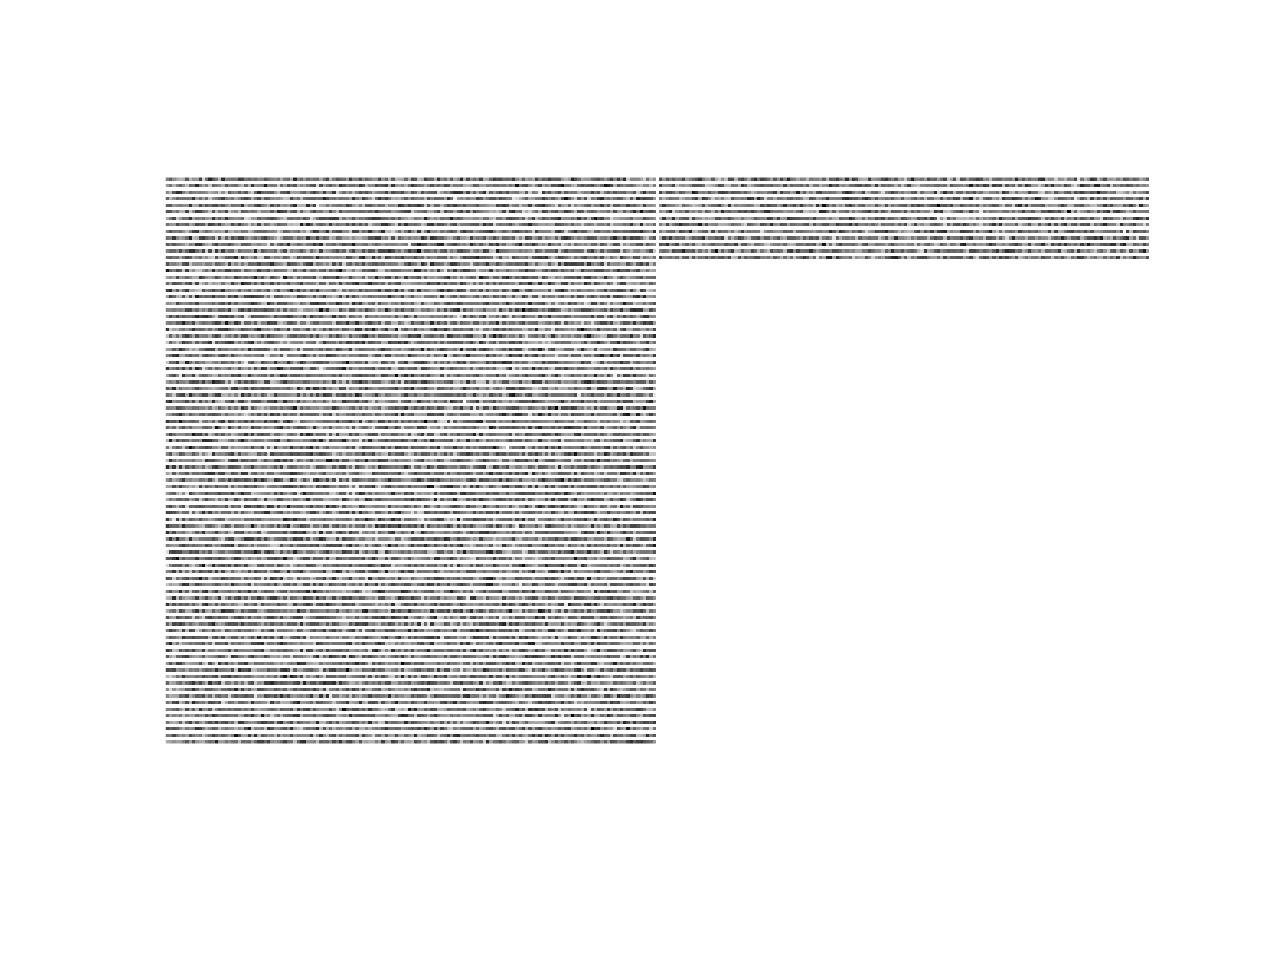

ans =   Image with properties:

           CData: [173x301 double]
    CDataMapping: 'scaled'

  Show all properties


figure()
plotWeights(autoencoder)

###  Encode and decode data using the trained autoencoder:

encoded_data = encode(autoencoder, data_sequence');
decoded_data = decode(autoencoder, encoded_data)';

% Display the results or perform further analysis
disp('Original Data:');

Original Data:


disp(data_sequence);

     1     1     0     0     0     0     0     0     0     1     1     1     0     1     0     1     1     0     1     0     1     1     1     1     0     0     1     1     0     1     0     0     0     1     1     0     1     1     1     1     1     1     1     0     0     0     1     0     1     0     1     0     0     0     1     0     0     0     0     1     0     0     1     1     1     1     1     0     0     1     0     1     1     0     0     0     1     0     0     0     1     0     0     0     0     0     0     0     1     0     0     0     0     0     0     1     1     1     1     1     0     1     1     0     1     1     0     0     1     0     1     0     0     0     1     0     0     1     1     0     1     0     1     1     1     0     1     0     1     1     0     1     1     1     1     1     1     0     1     1     1     1     1     1     0     0     1     0     1     1



disp('Decoded Data:');

Decoded Data:


disp(decoded_data);

    0.5347    0.7733    0.3533    0.3948    0.3562    0.4981    0.3479    0.3685    0.4475    0.3919    0.5100    0.5926    0.5036    0.6410    0.2313    0.6786    0.4169    0.4822    0.5138    0.3111    0.5840    0.6297    0.6297    0.5980    0.3304    0.3680    0.7221    0.5923    0.3459    0.6399    0.4447    0.6690    0.4888    0.7483    0.4477    0.4092    0.7055    0.5087    0.5572    0.6981    0.4655    0.7777    0.6575    0.3864    0.2157    0.4156    0.6694    0.3372    0.7432    0.3178    0.6578    0.3575    0.3038    0.4838    0.4777    0.3258    0.2757    0.3525    0.4665    0.6379    0.4082    0.3302    0.6556    0.6954    0.6590    0.6587    0.5121    0.4266    0.2509    0.5775    0.4460    0.5806    0.6458    0.6045    0.7534    0.3374    0.7757    0.4192    0.3000    0.3514    0.6572    0.4580    0.4696    0.3738    0.4806    0.2793    0.3488    0.4007    0.6765    0.3850    0.5364    0.4633    0.4336    0.3795    0.4373    0.4510    0.4996    0.7038    0.7966    0.4433

###  Encode and decode test data using the trained autoencoder:

encoded_test_data = encode(autoencoder, testData');
decoded_test_data = decode(autoencoder, encoded_test_data)';

### MSE and PSNR for Test data:

% Compute Mean Squared Error (MSE)
mse = immse(testData, decoded_test_data);
disp(['Mean Squared Error on Test Data: ', num2str(mse)]);

Mean Squared Error on Test Data: 0.17551


% Evaluate PSNR
psnrValue = psnr(decoded_test_data, testData);
disp(['PSNR on Test Data: ', num2str(psnrValue)]);

PSNR on Test Data: 7.5569


### Channel with AWGN noise + Rayleigh fading:

% Define channel parameters
SNR_dB = 10; % Signal-to-Noise Ratio in dB
SNR = 10^(SNR_dB/10); % Convert dB to linear scale
channel_coefficient = 1; % Channel coefficient (can represent fading)

% Generate random binary data
num_bits = 150;
data = randi([0, 1], 1, num_bits);

% Modulate the data (e.g., BPSK modulation)
modulated_data = 2 * data - 1;
encoded_data_channel = encode(autoencoder, data')';

% Add AWGN noise
noise = sqrt(1 / (2 * SNR)) * randn(1, hidden_size);

% Rayleigh fading
fading_channel = (1/sqrt(2)) * (randn(1, hidden_size) + 1i * randn(1, hidden_size));


% Simulate wireless transmission through the channel
transmitted_signal = channel_coefficient * encoded_data_channel; % You may include modulation if needed
% received_signal = awgn(transmitted_signal, SNR_dB); % Add AWGN noise
received_signal_with_fading = fading_channel .* transmitted_signal;
received_signal = channel_coefficient *  transmitted_signal + noise;

% Decode the received signal using the trained autoencoder
decoded_data = decode(autoencoder, received_signal');
decoded_data_2 = (real(decoded_data) > 0.5);
disp(data)

     0     0     1     0     1     1     1     1     0     1     1     0     1     1     1     1     1     1     0     0     0     0     1     0     0     0     1     1     1     0     0     0     1     0     1     0     0     1     1     1     0     1     0     1     1     0     0     0     1     1     1     0     0     0     1     1     1     1     0     0     0     1     1     1     0     1     0     1     1     1     0     1     0     1     1     0     1     1     0     1     0     0     0     0     1     0     1     0     1     0     0     0     1     1     0     1     0     1     1     1     0     0     1     0     0     1     0     0     0     1     1     1     0     0     0     0     0     0     1     0     1     0     1     0     1     0     0     1     0     0     0     1     1     1     0     1     1     0     0     1     1     0     1     1     1     0     0     1     0     0



### MSE for Channel decoded signal:

mse = immse(data, decoded_data');
disp(['Mean Squared Error on channel Data: ', num2str(mse)]);

Mean Squared Error on channel Data: 0.22493


### BER for Channel decoded signal:

% Compare Transmitted and Received Bits
incorrect_bits = sum(data ~= decoded_data_2');

% Calculate Bit Error Rate (BER)
BER = incorrect_bits / num_bits;

disp(['Bit Error Rate (BER): ', num2str(BER)]);

Bit Error Rate (BER): 0.35333


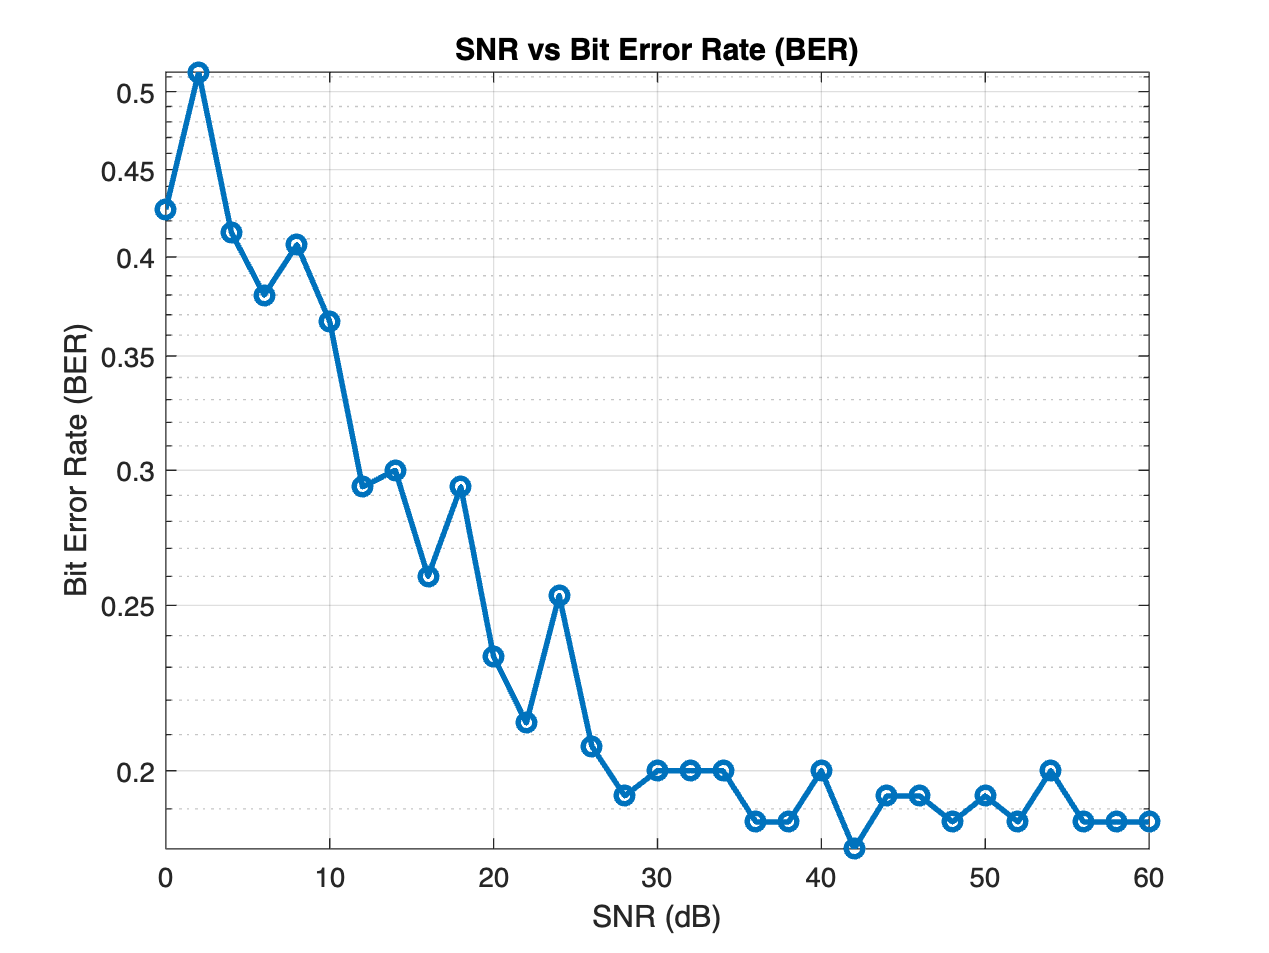

% Define SNR range
SNR_dB_range = 0:2:60;
num_simulations = length(SNR_dB_range);

% Initialize arrays to store results
BER_results = zeros(1, num_simulations);

% Loop over different SNR values
for i = 1:num_simulations
    SNR_dB = SNR_dB_range(i);
    SNR = 10^(SNR_dB/10);

    % Simulate wireless transmission through the channel
    noise = sqrt(1 / (2 * SNR)) * randn(1, hidden_size);
    received_signal = channel_coefficient * transmitted_signal + noise;

    % Decode the received signal using the trained autoencoder
    decoded_data = decode(autoencoder, received_signal');
    decoded_data_2 = (real(decoded_data) > 0.5);

    % Calculate Bit Error Rate (BER)
    incorrect_bits = sum(data ~= decoded_data_2');
    BER = incorrect_bits / num_bits;
    BER_results(i) = BER;
end

% Plot SNR vs BER
figure;
semilogy(SNR_dB_range, BER_results, 'o-', 'LineWidth', 2);
title('SNR vs Bit Error Rate (BER)');
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
grid on;

### Experiment with hyperparameter tuning and different autoencoder architectures to improve performance: 

hiddenSizes = [10, 20, 30];
sparsityValues = [0.01, 0.05, 0.1];
regularizationValues = [0.001, 0.01, 0.1];

bestAutoencoder = optimizeAutoencoder(trainData, hiddenSizes, sparsityValues, regularizationValues);

Best Parameters:
        hiddenSize: 30
          sparsity: 0.0500
    regularization: 0.1000

Best MSE: 0.24443


function bestAutoencoder = optimizeAutoencoder(trainData, hiddenSizes, sparsityValues, regularizationValues)
    % Initialize variables to store the best results
    bestMSE = Inf;
    bestParameters = struct();

    % Perform grid search over hyperparameters
    for hiddenSize = hiddenSizes
        for sparsity = sparsityValues
            for regularization = regularizationValues
                % Create autoencoder
                autoencoder = trainAutoencoder(trainData, hiddenSize, 'MaxEpochs', 5, ...
                    'EncoderTransferFunction', 'logsig', ...
                    'DecoderTransferFunction', 'purelin', ...
                    'SparsityProportion', sparsity, ...
                    'L2WeightRegularization', regularization);

                % Evaluate performance using Mean Squared Error (MSE)
                reconstructedData = predict(autoencoder, trainData);
                mse = immse(trainData, reconstructedData);

                % Update best parameters if MSE improves
                if mse < bestMSE
                    bestMSE = mse;
                    bestParameters.hiddenSize = hiddenSize;
                    bestParameters.sparsity = sparsity;
                    bestParameters.regularization = regularization;
                    bestAutoencoder = autoencoder;
                end
            end
        end
    end

    % Display best parameters
    disp('Best Parameters:');
    disp(bestParameters);
    disp(['Best MSE: ', num2str(bestMSE)]);
end